# Battery Analysis Script

by: Conrad Rowling - 7/4/20

Using MIT Data 

clc; clear; clf;
CellName = "Cell";
BatteryType = "VTC6";
StepInspect = false;
ShowFIT = false;
DoSave = true;

% input charge values to inspect the results from
% chg = [10 50 90];
% would be 10% 50% and 90%

ChargePoints = linspace(0,100);

%this outputs at every integer percentage


This needs to point to the place where the data files are stored, if this script and the data files are in different locations you need to provide the full path below:


TopFileLocation = 'MIT Motorsports Cell Data 2019\';
TopDirectory = dir(TopFileLocation);                      % directory
TopNames = {TopDirectory(:).name}';                       % get the names of all files from the directory

AllCellNames = TopNames(startsWith(TopNames,CellName)); % search for ones that start with cellName
AllCellNumbers = fullfile(AllCellNames);                       % full file location of search results


Most of this code is just sorting files, and creating a directory of the files that are of interest

It allows easy selection of individual cells, to troubleshoot coding (so the script won't run for 20+ min)

sorted_IR_40 = [];
sorted_IR_60 = [];
sorted_V_40 = [];
sorted_V_60 = [];

for j = 1:length(AllCellNumbers)
    
    % Using the same methodology as above, the tests are separated by which
    % temperature they are ran at.
    
    CellDirectory = dir(strcat(TopFileLocation,char(AllCellNumbers(j))));
    FileNames = {CellDirectory(:).name}';
    CellNames = FileNames(startsWith(FileNames, BatteryType));
    Degrees40Files = CellNames(contains(CellNames,"_40_"));
    Degrees60Files = CellNames(contains(CellNames,"_60_"));
    Degrees40CSV = fullfile(strcat(TopFileLocation,char(AllCellNumbers(j))),Degrees40Files);
    Degrees60CSV = fullfile(strcat(TopFileLocation,char(AllCellNumbers(j))),Degrees60Files);
    
    Fit_IR_40 = [];
    Fit_IR_SOC_40 = [];
    Fit_IR_60 = [];
    Fit_IR_SOC_60 = [];
    Fit_V_40 = [];
    Fit_V_SOC_40 = [];
    Fit_V_60 = [];
    Fit_V_SOC_60 = [];
    

## Analysis:

**Cycle Dependence:**

Since all of the cells were cylced for less than 100 times, I assumed the test where independent of each other (life time >1000 cycles for these batteries, and there is little change between them)

given that assumption, the data was vertically concatenated and fit as one data set per given temperature.

**Data Extraction:**

The peakfilter function looks through the code for large current spikes and samples the data around it, If passed a "voltage" analysis all the data surrounding the spikes is removed, whereas an "IR" analysis removes all the data except the spikes.

The spikes are used to find purely Ohmic resistance (although that was not feasible since the sample times of the data is ~0.1s, too slow to ignore a transient response) **this script analyzes the data 0.3 seconds before and after the interupt **(this was justified from data inspection, and can be repeated with the inspectSteps option)

**More details** on the method to find internal resistance: it is called current interrupt more info can be found on the link below:

[https://www.batterypoweronline.com/articles/how-to-measure-battery-internal-resistance-using-the-current-interrupt-method/](https://www.batterypoweronline.com/articles/how-to-measure-battery-internal-resistance-using-the-current-interrupt-method/)

            
        for i = 1:length(Degrees40CSV)
           Temp_40 = importfile(char(Degrees40CSV(i)));                                            %this means temporary not temperature
            [Cell(j,i).Raw.Temp40.IR, Cell(j,i).Raw.Temp40.IR_SOC] ...
                = PeakFilter1(Temp_40.Amps,Temp_40.Volts,Temp_40.Times, "IR");
            [Cell(j,i).Raw.Temp40.VOLTAGE, Cell(j,i).Raw.Temp40.V_SOC] ...
                = PeakFilter1(Temp_40.Amps,Temp_40.Volts,Temp_40.Times, "VOLTAGE");
            Fit_IR_40 = vertcat(Fit_IR_40, Cell(j,i).Raw.Temp40.IR);
            Fit_IR_SOC_40 = vertcat(Fit_IR_SOC_40, Cell(j,i).Raw.Temp40.IR_SOC);
            Fit_V_40 = vertcat(Fit_V_40, Cell(j,i).Raw.Temp40.VOLTAGE);
            Fit_V_SOC_40 = vertcat(Fit_V_SOC_40, Cell(j,i).Raw.Temp40.V_SOC);         
        end
        for k = 1:length(Degrees60CSV)
            Temp_60 = importfile(char(Degrees60CSV(k)));                                            %this means temporary not temperature
            [Cell(j,k).Raw.Temp60.IR, Cell(j,k).Raw.Temp60.IR_SOC] ...
                = PeakFilter1(Temp_60.Amps, Temp_60.Volts, Temp_60.Times, "IR");
            [Cell(j,k).Raw.Temp60.VOLTAGE, Cell(j,k).Raw.Temp60.V_SOC] ...
                = PeakFilter1(Temp_60.Amps, Temp_60.Volts, Temp_60.Times, "VOLTAGE");
            Fit_IR_60 = vertcat(Fit_IR_60, Cell(j,k).Raw.Temp60.IR);
            Fit_IR_SOC_60 = vertcat(Fit_IR_SOC_60, Cell(j,k).Raw.Temp60.IR_SOC); 
            Fit_V_60 = vertcat(Fit_V_60, Cell(j,k).Raw.Temp60.VOLTAGE);
            Fit_V_SOC_60 = vertcat(Fit_V_SOC_60, Cell(j,k).Raw.Temp60.V_SOC);
            
        end
        sorted_40_temp = [Fit_IR_SOC_40, Fit_IR_40];
        sorted_IR_40 = vertcat(sorted_IR_40,sorted_40_temp);
        sorted_60_temp = [Fit_IR_SOC_60, Fit_IR_60];
        sorted_IR_60 = vertcat(sorted_IR_60, sorted_60_temp);
        sorted_40_2_temp = [Fit_V_SOC_40, Fit_V_40];
        sorted_V_40 = vertcat(sorted_V_40,sorted_40_2_temp);
        sorted_60_2_temp = [Fit_V_SOC_60, Fit_V_60];
        sorted_V_60 = vertcat(sorted_V_60, sorted_60_2_temp);
        
%     [Voltage_FitCurve(j).Temp40.fit, Voltage_FitCurve(j).Temp40.gof] = GenerateFit(Fit_V_SOC_40, Fit_V_40, BatteryType, "VOLTAGE");
%     [Voltage_FitCurve(j).Temp60.fit, Voltage_FitCurve(j).Temp60.gof] = GenerateFit(Fit_V_SOC_60, Fit_V_60, BatteryType, "VOLTAGE");


## Fitting Data

To fit the data I used the cftool to fit data from all the cycles from one cell, and then used that fit for all of the other cells (since the behaviour should be fairly independent of cell # if all cells are at approx. the same "life stage"). I generated the most Ideal fits for the given data, IR was a much more complicated curve and I used a smoothing spline, where as Voltage could be fit with a polynomial. Once all the cells have a fit you can plug whatever charge percentages and it will respond with the given Internal resistance. To generate results all of the data between all the curves are averaged, and output as "Results" - which includes standard deviation    

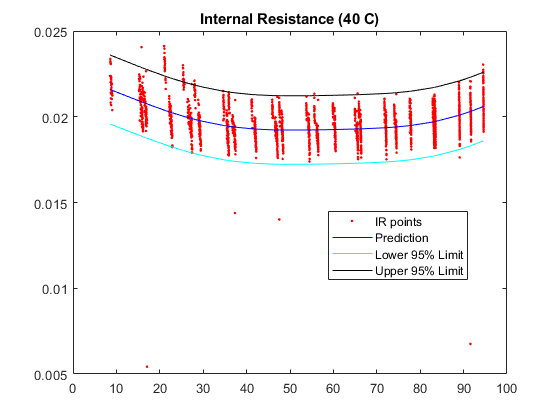

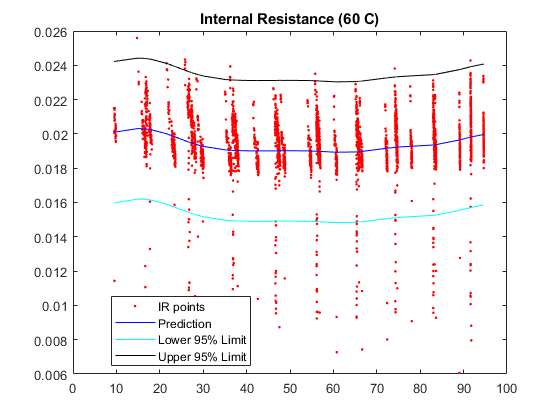

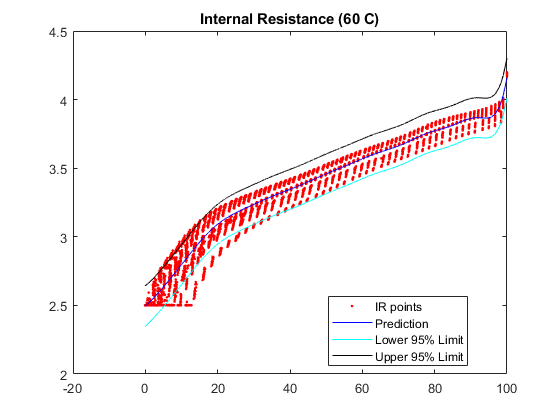

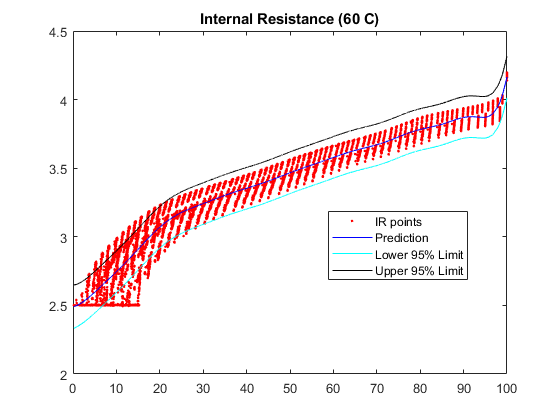

    if ShowFIT
        %To display the fits relative to the data if desired
        figure()
        plot(IR_FitCurve(j).Temp40.fit,Fit_IR_SOC_40, Fit_IR_40)
        legend("IR", 'fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
        % Label axes
        xlabel( 'S.O.C (%)', 'Interpreter', 'none' );
        ylabel( "IR" + ' (40 degrees)', 'Interpreter', 'none' );
        grid on 
        hold on
        plot(Voltage_FitCurve(j).Temp60.fit,Fit_V_SOC_40, Fit_V_40)
        legend('Voltage', 'fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
        % Label axes
        xlabel( 'S.O.C (%)', 'Interpreter', 'none' );
        ylabel( 'Voltage (60 degrees)', 'Interpreter', 'none' );
        grid on
        hold on
    end
    
    Fit_IR_40 = [];
    Fit_IR_SOC_40 = [];
    Fit_IR_60 = [];
    Fit_IR_SOC_60 = [];
    Fit_V_40 = [];
    Fit_V_SOC_40 = [];
    Fit_V_60 = [];
    Fit_V_SOC_60 = [];
end

%Bat :
%   Cell 1
%   Cell 10
%   Cell 100
%   Cell 2
%   Cell 3
%    .
%    .
%    .
%   Cell 9
sorted_IR_40 = sortrows(sorted_IR_40);
sorted_IR_60 = sortrows(sorted_IR_60);
sorted_V_40 = sortrows(sorted_V_40);
sorted_V_60 = sortrows(sorted_V_60);

gprMdl_IR_40 = fitrgp(sorted_IR_40(:,1),sorted_IR_40(:,2));
[pred1,~,ci1] = predict(gprMdl_IR_40,sorted_IR_40(:,1));
figure();
plot(sorted_IR_40(:,1),sorted_IR_40(:,2),'r.','DisplayName','IR points');  
hold on
plot(sorted_IR_40(:,1),pred1,'b','DisplayName','Prediction');
plot(sorted_IR_40(:,1),ci1(:,1),'c','DisplayName','Lower 95% Limit');
plot(sorted_IR_40(:,1),ci1(:,2),'k','DisplayName','Upper 95% Limit');
legend('show','Location','Best');
title('Internal Resistance (40 C)')
shg;

gprMdl_IR_60 = fitrgp(sorted_IR_60(:,1),sorted_IR_60(:,2));
[pred2,~,ci2] = predict(gprMdl_IR_60,sorted_IR_60(:,1));
figure();
plot(sorted_IR_60(:,1),sorted_IR_60(:,2),'r.','DisplayName','IR points');  
hold on
plot(sorted_IR_60(:,1),pred2,'b','DisplayName','Prediction');
plot(sorted_IR_60(:,1),ci2(:,1),'c','DisplayName','Lower 95% Limit');
plot(sorted_IR_60(:,1),ci2(:,2),'k','DisplayName','Upper 95% Limit');
legend('show','Location','Best');
title('Internal Resistance (60 C)')
shg;
gprMdl_V_40 = fitrgp(sorted_V_40(:,1),sorted_V_40(:,2),'PredictMethod',"exact");
[pred2,~,ci3] = predict(gprMdl_V_40,sorted_V_40(:,1));
figure();
plot(sorted_V_40(:,1),sorted_V_40(:,2),'r.','DisplayName','IR points');  
hold on
plot(sorted_V_40(:,1),pred2,'b','DisplayName','Prediction');
plot(sorted_V_40(:,1),ci3(:,1),'c','DisplayName','Lower 95% Limit');
plot(sorted_V_40(:,1),ci3(:,2),'k','DisplayName','Upper 95% Limit');
legend('show','Location','Best');
title('Internal Resistance (60 C)')
shg;

gprMdl_V_60 = fitrgp(sorted_V_60(:,1),sorted_V_60(:,2),'PredictMethod',"exact");
[pred2,~,ci4] = predict(gprMdl_V_60,sorted_V_60(:,1));
figure();
plot(sorted_V_60(:,1),sorted_V_60(:,2),'r.','DisplayName','IR points');  
hold on
plot(sorted_V_60(:,1),pred2,'b','DisplayName','Prediction');
plot(sorted_V_60(:,1),ci4(:,1),'c','DisplayName','Lower 95% Limit');
plot(sorted_V_60(:,1),ci4(:,2),'k','DisplayName','Upper 95% Limit');
legend('show','Location','Best');
title('Internal Resistance (60 C)')
shg;

## Inspecting Interrupts

This allows inspection of the interrupt timing, it was used to validate the sampling methodology - justifying how long to sample the voltage rise (~ 0.3 sec) - this ensured data wasnt missing and ignored prolonged transients

if StepInspect == true
    subplot(2,1,1)
    plot(0:0.1:2.5 ,Temp_40.Amps(3970:3995)), ylabel("Current (A)");
    subplot(2,1,2)
    plot(0:0.1:2.5 ,Temp_40.Volts(3970:3995)), ylabel ("Voltage (V)"), xlabel("Times (s)");
end

## Processing Results

This fills in a results object, by plugging the charge percentages into the fits, and then organizing them into a matrix of # of cells (column) and # of charge % (rows). Then they get averaged by each row.

% for i = 1:length(AllCellNumbers)
% %       Data(1).raw.temp40(:,i) =  IR_FitCurve(i).Temp40.fit(ChargePoints);
% %       Data(1).raw.temp60(:,i) =  IR_FitCurve(i).Temp60.fit(ChargePoints);
%       Data(2).raw.temp40(:,i) =  Voltage_FitCurve(i).Temp40.fit(ChargePoints);
%       Data(2).raw.temp60(:,i) =  Voltage_FitCurve(i).Temp60.fit(ChargePoints);
% end
% 
% for i = 1:length(Data)
%     Data(i).mean(:,1) = mean(Data(i).raw.temp40,2);
%     Data(i).std(:,1) = std(Data(i).raw.temp40,0,2);
%     Data(i).mean(:,2) = mean(Data(i).raw.temp60,2);
%     Data(i).std(:,2) = std(Data(i).raw.temp60,0,2);
% end
% 
% Results.mean.temp40 = [ChargePoints.',Data(1).mean(:,1), Data(2).mean(:,1)];
% Results.std.temp40 = [ChargePoints.',Data(1).std(:,1), Data(2).std(:,1)];
% Results.mean.temp60 = [ChargePoints.',Data(1).mean(:,2), Data(2).mean(:,2)];
% Results.std.temp60 = [ChargePoints.',Data(1).std(:,2), Data(2).std(:,2)];
Results.IR.temp40 = gprMdl_IR_40;
Results.IR.temp60 = gprMdl_IR_60;
Results.Voltage.temp40 = gprMdl_V_40;
Results.Voltage.temp60 = gprMdl_V_60;


## Object Creation

This is an object creation script that blake wrote, and I edited for the scope of this analysis, to create these output files, the two class definitions needed to be added to your path

**And you need to change : **

to where you want the output files to go

if DoSave
    addpath('C:\Users\cdrow\Documents\GitHub\MIT-Cell-Analysis' );
    name = BatteryType + '_' + 'IR_V' +'_SOC';
            RESULTS = InternalResistance( 'FE8', Results, BatteryType);
    
    cd( 'C:\Users\cdrow\Desktop\UCDavis\Spring 2020\Senior Design\MIT Cell Analysis' )
    save( [RESULTS.Name, '.mat'], 'RESULTS' );
end

function [Data] = importfile(filename, dataLines)
    if nargin < 2
        dataLines = [7, Inf];
    end

    opts = delimitedTextImportOptions("NumVariables", 6);

    % Specify range and delimiter
    opts.DataLines = dataLines;
    opts.Delimiter = ",";

    % Specify column names and types
    opts.VariableNames = ["Times", "Volts", "Amps", "Var4", "Var5", "Var6"];
    opts.SelectedVariableNames = ["Times", "Volts", "Amps"];
    opts.VariableTypes = ["double", "double", "double", "string", "string", "string"];

    % Specify file level properties
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";

    % Specify variable properties
    opts = setvaropts(opts, ["Var4", "Var5", "Var6"], "WhitespaceRule", "preserve");
    opts = setvaropts(opts, ["Var4", "Var5", "Var6"], "EmptyFieldRule", "auto");

    % Import the data
    Q14023 = readtable(filename, opts);
    
    % Convert to output type
    Data.Times = Q14023.Times;
    Data.Volts = Q14023.Volts;
    Data.Amps = Q14023.Amps;
end

function [DATA, SOC] = PeakFilter1(i, v, time, select)
    di = diff(i);
    v2 = v;
    di(1:500) = [];
    v(1:500) = [];
   

    %finding the average with the zeros removed
    temp1 = di(di~=0);
    avgI = mean(temp1);
    
    % this is all resizing the data to be the same length:
    % cutting off initial & terminal noise 
    di(length(di)-400:length(di)) = [];
    v(length(v)-1) =[];
    v(length(v)-400:length(v)) = [];
    
    soc = 100 - cumsum([0; diff(time)].*i./10800.*100);
    fsoc = soc;
    soc(1:501) = [];
    soc(length(soc)-400:length(soc)) = [];
    
    Vselect = zeros(length(v), 1);
    dI = zeros(length(v), 1);
    dV = zeros(length(v),1);
    filter = zeros(length(v), 1);
    filterNot = ones(length(v2), 1);
    
    di(1:4) = 0;
    % this loop finds current interupts above a threshold (100 x avg)
    % then creates a voltage array with the values surrounding the peaks
    
    for i = 4:length(di)
        if (di(i) <= (50*avgI))
            di(i) = 0;
        elseif (di(i) > (50*avgI)) && (3 < i < length(di)-4)
            for j = -3:3
                Vselect(i + j) = v(i+j);
            end
        end
    end
    
    %this computes the total initial current change
    %and the voltage change around it
    %once it finds a peak it skips ahead to ignore subsequent changes
    
%      IR = [Vselect, di];
%      IR( ~any(IR,2), : ) = [];
    
    k = 4;
    while k  < length(di)
        sumdI = 0;
        if (di(k) ~= 0)
            filter(k) = 1;
            filterNot(500+k) = 0;
            for h = -20:20
                filterNot(k+h+500) = 0;
            end
            for j = -3:3 
                nextdI = di(k + j);
                sumdI = sumdI + nextdI;
            end 
            dV(k) = Vselect(k -3) - Vselect(k + 3);
            dI(k) = sumdI;
            k = k + 3;
        end
        k = k + 1;
    end
    
    fsoc = fsoc.*filterNot;
    VOLT = v2.*filterNot;
    fsoc = fsoc(fsoc~=0);
    VOLT = VOLT(VOLT~=0);
    
    soc = soc.*filter;
    SOC = soc(soc~=0);
    dV = dV(dV~=0);
    dI = dI(dI~=0);
    IR = dV./dI;
    
    if select == "VOLTAGE"
        SOC = fsoc;
        DATA = VOLT;
        x = 0;
        FILTER = zeros(length(DATA));
        for r = 1:length(DATA)
            if r - x > 200
                FILTER(r) = 1;
                x = r;
            end
        end
        FILTER(1) = 1;
        FILTER(length(DATA)-1) = 1;
        DATA = FILTER.*DATA;
        SOC = FILTER.*SOC;
        DATA = DATA(DATA~=0);
        SOC = SOC(SOC~=0);
    else 
        DATA = IR;
    end
end

function [fitResult, gof] = GenerateFit(x, y, select1, select2)

    % Each of these different fits were created by analyzing the behavior of
    % one cell, using cftool and then used the same fit for all the other
    % cells. the fit is good. The plots can be inspected by checking
    % showFIT at the top of the script
    
    [xData, yData] = prepareCurveData( x, y );
    switch select1
        case "VTC6"
            switch select2
                case "IR"
%                     Set up fittype and options.
                    ft = fittype( 'smoothingspline' );
                    opts = fitoptions( 'Method', 'SmoothingSpline' );
                    opts.SmoothingParam = 20e-4;
%                     Fit model to data.
                    [fitResult, gof] = fit( xData, yData, ft, opts );

                case "VOLTAGE"
                    % Set up fittype and options.
                    ft = fittype( 'smoothingspline' );
                    opts = fitoptions( 'Method', 'SmoothingSpline' );
                    opts.SmoothingParam = 0.0013651568620810163;
                    % Fit model to data.
                    [fitResult, gof] = fit( xData, yData, ft, opts );                    
            end
        case "30Q"
            switch select2
                case "IR"
                    % Set up fittype and options.
                    ft = fittype( 'smoothingspline' );
                    opts = fitoptions( 'Method', 'SmoothingSpline' );
                    opts.SmoothingParam = 0.00165725505892051;
                    % Fit model to data.
                    [fitResult, gof] = fit( xData, yData, ft, opts );                    
                case "VOLTAGE"
                    ft = fittype( 'poly9' );
                    opts = fitoptions( 'Method', 'LinearLeastSquares' );
                    opts.Robust = 'LAR';
                    % Fit model to data.
                    [fitResult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );
            end

    end
end
